## Example: State-Space Representation Model

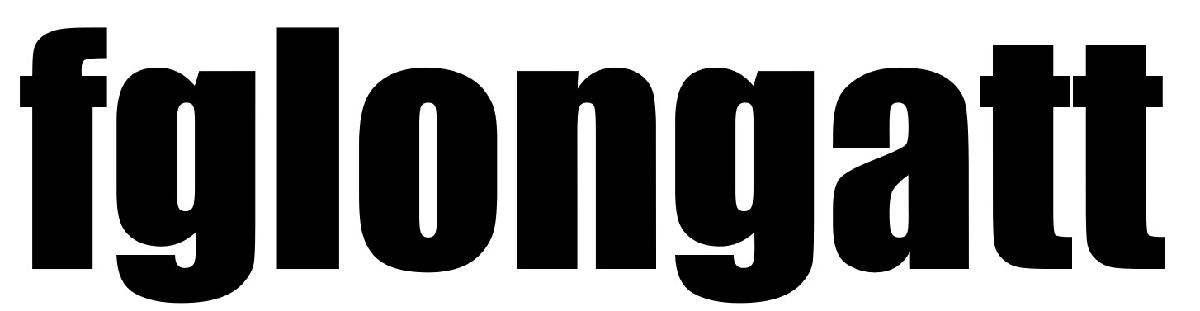  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

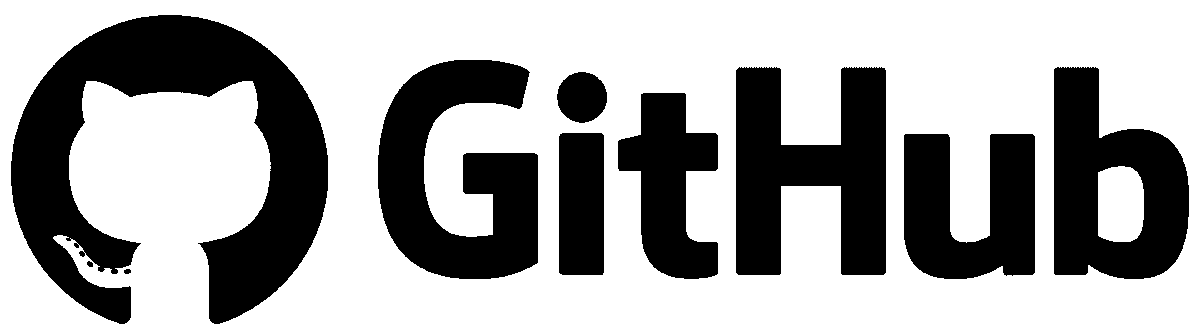 [https://github.com/fglongatt](https://github.com/fglongatt) 

06th September 2023

Thanks to Mr Jose Martin Valles for checking the final version.

Considers simple excitation system shown in Chapter 3,*Modal Analysis of Power Systems of the book *[1] (Page 33), see Figure 1.

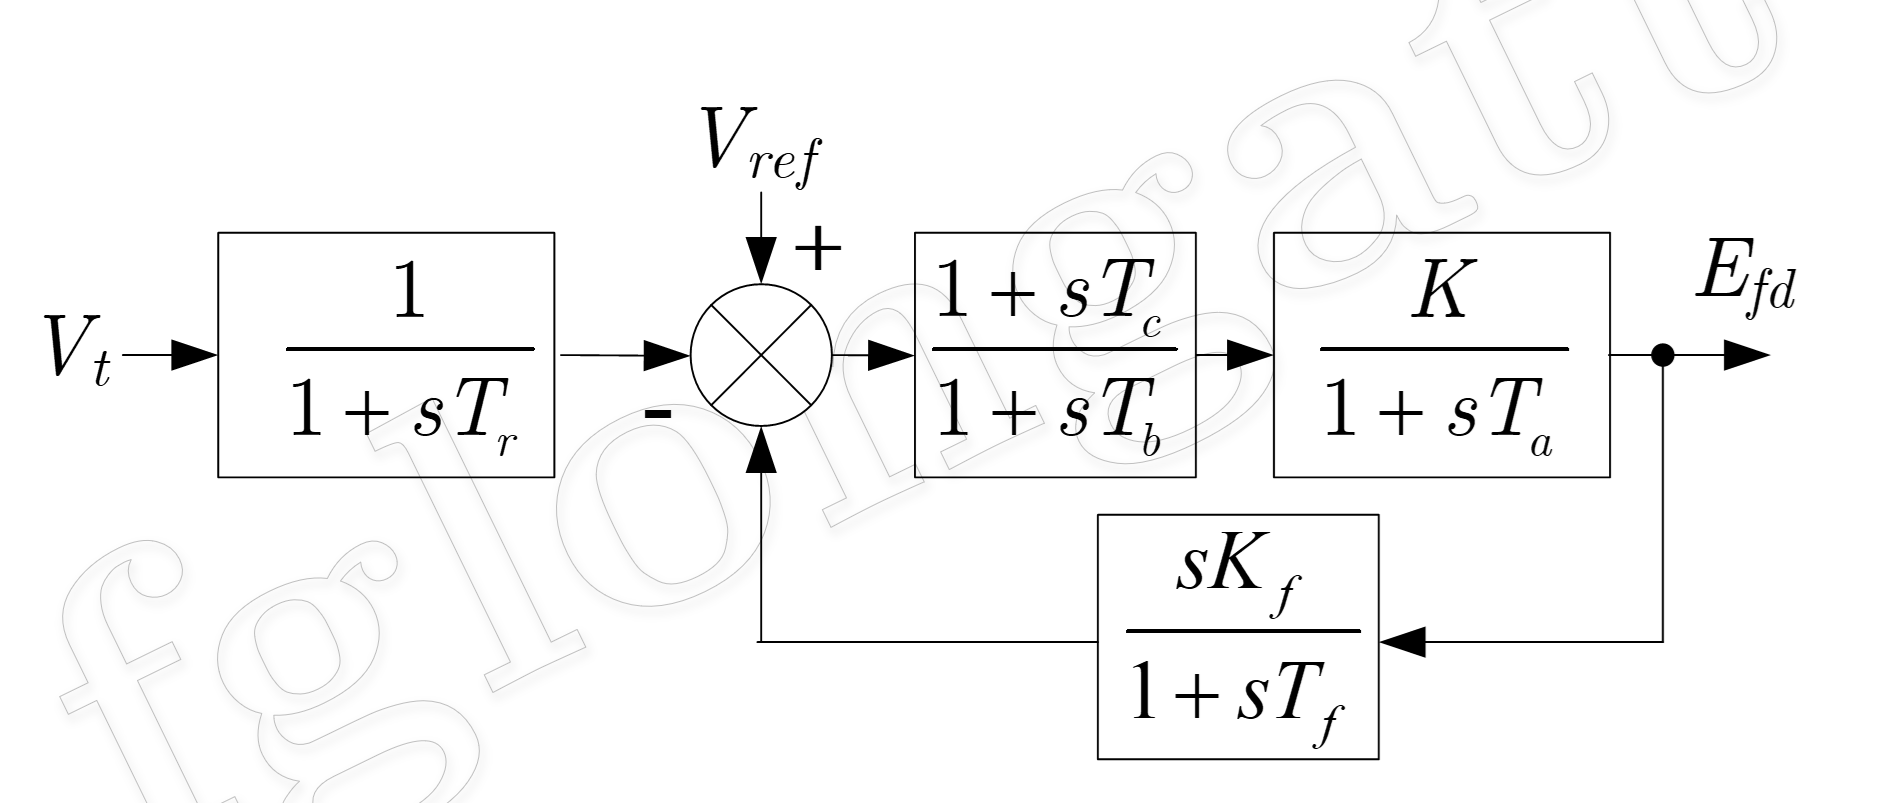

**Figure 1.** Block diagram of a simple exciter. Source: [1]

The **state-space model representation** of the dynamic system is:

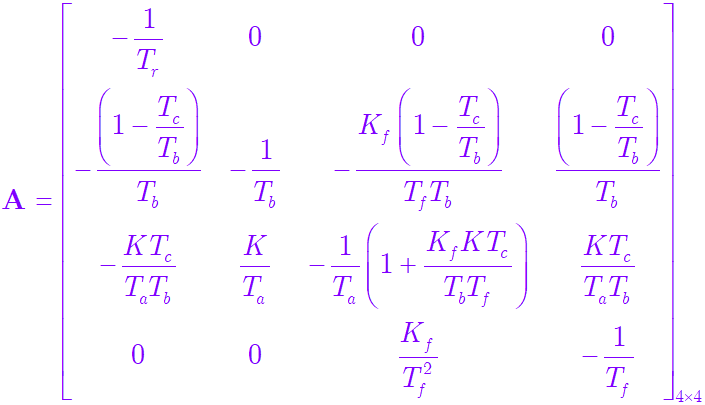           Equation (1)

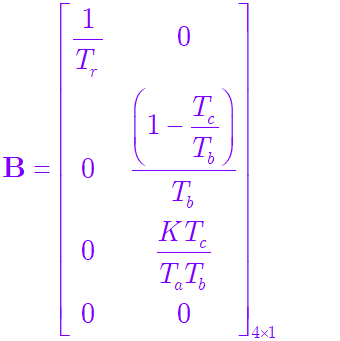                                                                    Equation (2)

                                                                              Equation (3)

                                                                                         Equation (4)

Detalies explanation of the model available at:

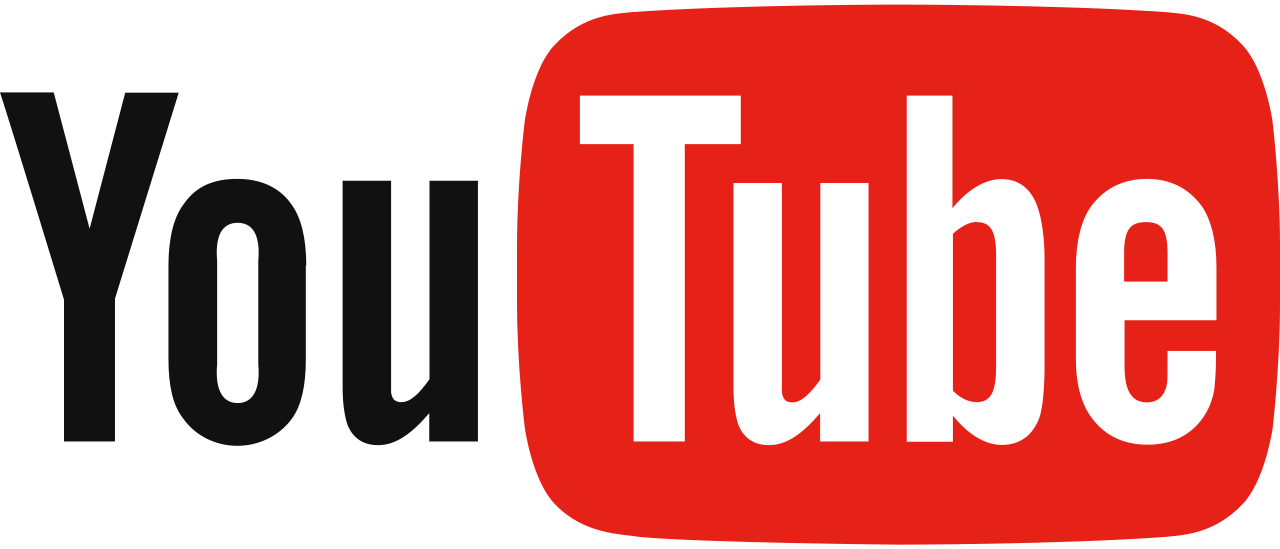 [https://youtu.be/2WMhzmSTuxE](https://youtu.be/2WMhzmSTuxE) (English Audio)

           [https://youtu.be/goTfkFwD5aE](https://youtu.be/goTfkFwD5aE) (Spanish Audio)

*Reference: *[1] G. Rogers, Power system oscillations. Boston, [Mass.] ; London: *Kluwer Academic*, 2000.

clc
clearvars

## Input data

Tr = 1.0    % Tr : Transducer time constant in seconds

Tr = 1

Tc = 1.0    % Tc: Voltage regulator time constant in seconds

Tc = 1

Tb = 1.5    % Tb: Voltage regulator time constant in seconds

Tb = 1.5000

K = 0.1     % K:  Voltage regulator gain

K = 0.1000

Ta = 1.0    % Ta: Voltage regulator time constant in seconds

Ta = 1

Kf = 1      % Kf: Excitation control system stabilizer gains

Kf = 1

Tf = 0.75   % Tf: Excitation control system stabilizer time constant

Tf = 0.7500

Creating the state matrix **A** as defined in Equation  (1).

Nstates = 4;    % Nstates : Number of states
Ninputs = 2;    % Ninputs : Number of inputs
Noutputs = 1;   % Noutpus: Number of outputs
A = zeros(Nstates);
% Row 1 - Matrix A
A(1,1) = -1/Tr ;
% Row 2 - Matrix A
KK = (1 - (Tc/Tb)) / Tb;
A(2,1) = -KK;
A(2,2) = -1/Tb;
A(2,3) = (Kf/Tf) * (-KK);
A(2,4) = KK;
% Row 3 - Matrix A
A(3,1) = -(K*Tc) / (Tb*Ta);
A(3,2) = K / Ta ;
A(3,3) = (((Kf*Tc*K) / (Tf*Tb))+1) * (-1/Ta);
A(3,4) = (K*Tc) / (Ta*Tb);
% Row 4 - Matrix A
A(4,3) = Kf / (Tf^2);
A(4,4) = -1/Tf ;

Creating the input matrix **B** as defined in Equation (2).

B = zeros(Nstates,Ninputs);
% Row 1 - Matrix B
B(1,1) = 1/Tr ;
% Row 2 - Matrix B
B(2,2) = KK;
% Row 3 - Matrix B
B(3,2) = (K*Tc)/(Ta*Tb);
% Row 4 - Matrix B
B(4,2) = 0;

Creating the state matrix **C** as defined in Equation (3).

C = zeros(1,Nstates);
C(1,3) = 1;

Creating the state maxtrix **D** as defined in Equation (4).

D = zeros(Noutputs,Ninputs);
D(1,1) = 0;
D(1,2) = 0;

## Creating the state-space representation

fprintf('State-Space representation')

State-Space representation

fprintf('------------------------------------')

------------------------------------

Use the command `ss(A,B,C,D)` to create real-valued or complex-valued state-space models, or to convert dynamic system models to state-space model form.

sys = ss(A,B,C,D,...
    'StateName',{'x_1' 'x_2' 'x_3' 'x_4'},...
    'InputName',{'VT' 'Vref'},'OutputName','Efd')

sys =
 
  A = 
             x_1       x_2       x_3       x_4
   x_1        -1         0         0         0
   x_2   -0.2222   -0.6667   -0.2963    0.2222
   x_3  -0.06667       0.1    -1.089   0.06667
   x_4         0         0     1.778    -1.333
 
  B = 
             VT     Vref
   x_1        1        0
   x_2        0   0.2222
   x_3        0  0.06667
   x_4        0        0
 
  C = 
        x_1  x_2  x_3  x_4
   Efd    0    0    1    0
 
  D = 
          VT  Vref
   Efd     0     0
 
Continuous-time state-space model.


## I. Time-domain Step response: State-Space Model

Step response plot of dynamic system is created using the command step(sys).

Tfinal = 20;    % Defining the final time of the step response
fprintf('Step response using State-Space model')

Step response using State-Space model

fprintf('------------------------------------')

------------------------------------

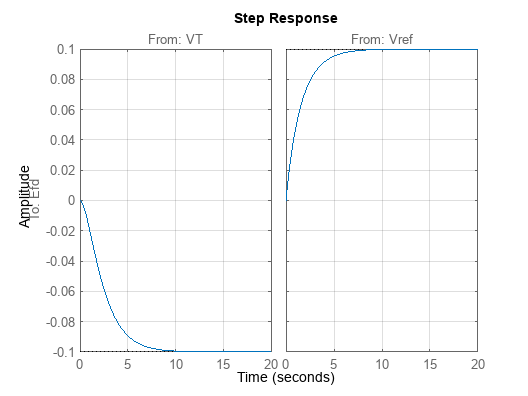

step(sys,Tfinal);
grid on

This is a dynamic system with two inputs and one output, so the plot of the step reponse shows the step response to each one fo the inputs independently considering the other zero.

### Creating the transfer fucntion for each entry

Use `tf` to create real-valued or complex-valued transfer function models, or to convert dynamic system models to transfer function form

fprintf(' Transfer function using the State-space model')

 Transfer function using the State-space model

fprintf('------------------------------------')

------------------------------------

Gc = tf(sys)

Gc =
 
  From input "VT" to output "Efd":
        -0.06667 s^2 - 0.1556 s - 0.08889
  ----------------------------------------------
  s^4 + 4.089 s^3 + 6.067 s^2 + 3.867 s + 0.8889
 
  From input "Vref" to output "Efd":
   0.06667 s^2 + 0.1556 s + 0.08889
  ----------------------------------
  s^3 + 3.089 s^2 + 2.978 s + 0.8889
 
Continuous-time transfer function.


Calculating the steady state value using the command dcgain()

fprintf(' Steady-state value using the State-space model')

 Steady-state value using the State-space model

fprintf('------------------------------------')

------------------------------------

ss_valueS = dcgain(Gc)

ss_valueS =    -0.1000    0.1000


Selecting the transfer function (1) related to the Vt, and calcualting the step resonse

fprintf('Step response using STATE-SPACE model')

Step response using STATE-SPACE model

fprintf('------------------------------------')

------------------------------------

Plotting the results:

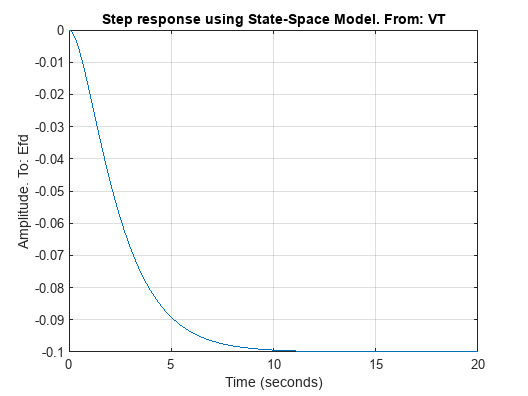

figure
[Efd,tOut] = step(Gc(1),Tfinal);
yss = timeseries(Efd,tOut);
plot(yss)
hold on
grid on
title('Step response using State-Space Model. From: VT')
ylabel('Amplitude. To: Efd')
xlabel('Time (seconds)')

## Validation of the Step Response

fprintf(' VALIDATION OF THE RESULTS USING SIMULINK MODEL')

 VALIDATION OF THE RESULTS USING SIMULINK MODEL

fprintf('------------------------------------')

------------------------------------

## II. Time-domain Step response: Simulink Model

The step response of the state-space model devirated above is compeared with the step responde of the same dynamic system but implemented explicitly using simulink

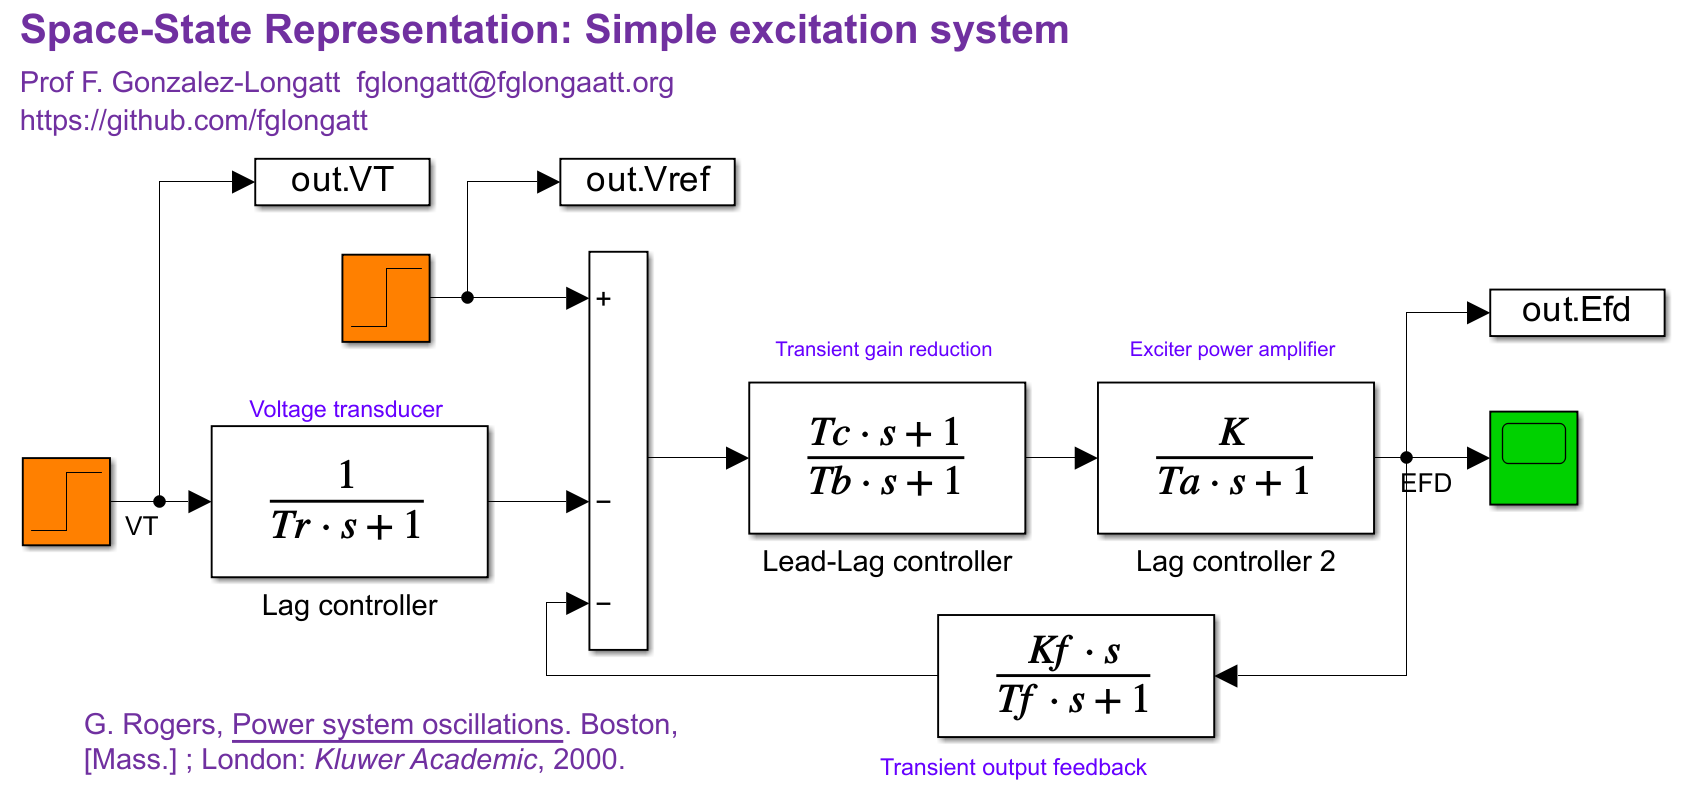

**NOTE: **This script require the Simulink model: **Example_SS_Exciter_Rogers.slx**

Calculating the state space presentation of the Simulink model:

FILE_NAME='Example_SS_Exciter_Rogers.slx';
fprintf(' State-space model of Simulink model')

 State-space model of Simulink model

[A1, B1, C1, D1]= linmod('Example_1_SS_Rogers2021')

A1 =    -1.0889   -0.6667    1.1852    0.2222
         0   -1.0000         0         0
    0.1000         0   -1.3333         0
   -0.1333   -1.0000    1.7778   -0.6667



B1 =

  4×0 empty double matrix


C1 =

  0×4 empty double matrix


D1 =

     []



fprintf('------------------------------------')

------------------------------------

Running a time-domian simulation (step response) of the Simulink model:

out = sim(FILE_NAME,'StopTime', num2str(Tfinal));
ysim = out.Efd;
fprintf('Step response using SIMULINK model')

Step response using SIMULINK model

fprintf('------------------------------------')

------------------------------------

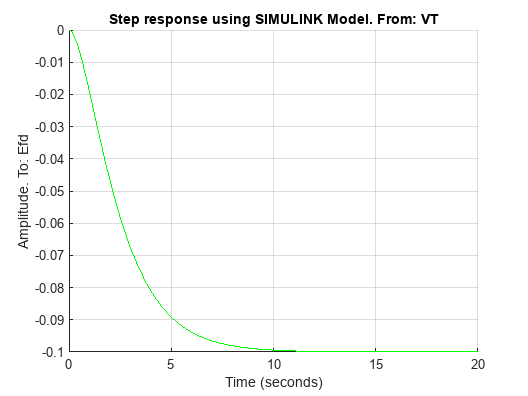

figure
hold on
plot(ysim,'g')
grid on
title('Step response using SIMULINK Model. From: VT')
ylabel('Amplitude. To: Efd')
xlabel('Time (seconds)')

## III. Time-domain Step response: Comparison

fprintf('Comparison')

Comparison

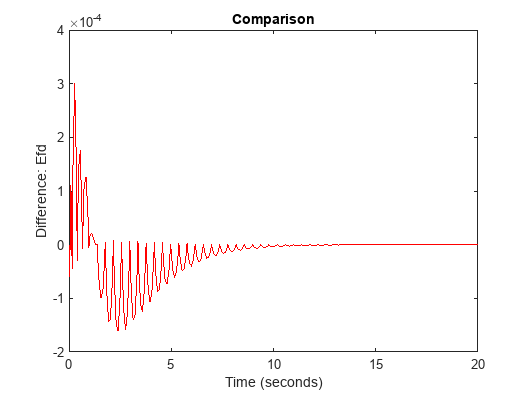

synchronizemethod = 'Union' ;
[ts1,ts2] = synchronize(yss,ysim,synchronizemethod);
d = (ts1-ts2);
figure
plot(ts1-ts2,'r')
title('Comparison')
ylabel('Difference: Efd')
xlabel('Time (seconds)')

#### Be part of our community 

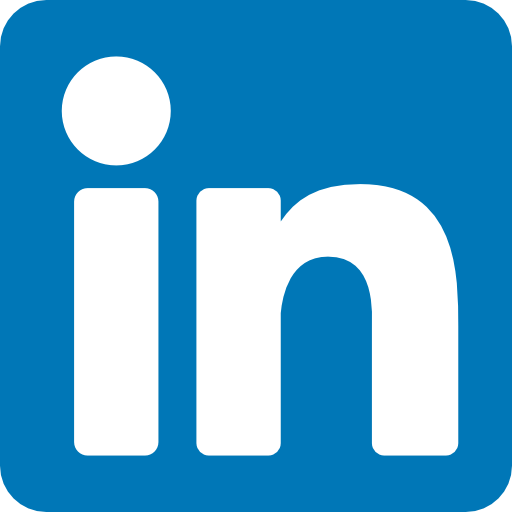 [https://www.linkedin.com/in/francisco-gonzalez-longatt/](https://www.linkedin.com/in/francisco-gonzalez-longatt/) 

 [https://www.youtube.com/user/fmglongatt](https://www.youtube.com/user/fmglongatt) 

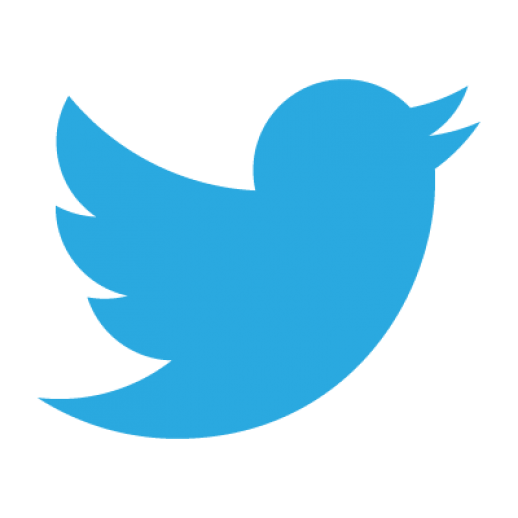 [https://twitter.com/fglongatt](https://twitter.com/fglongatt) 

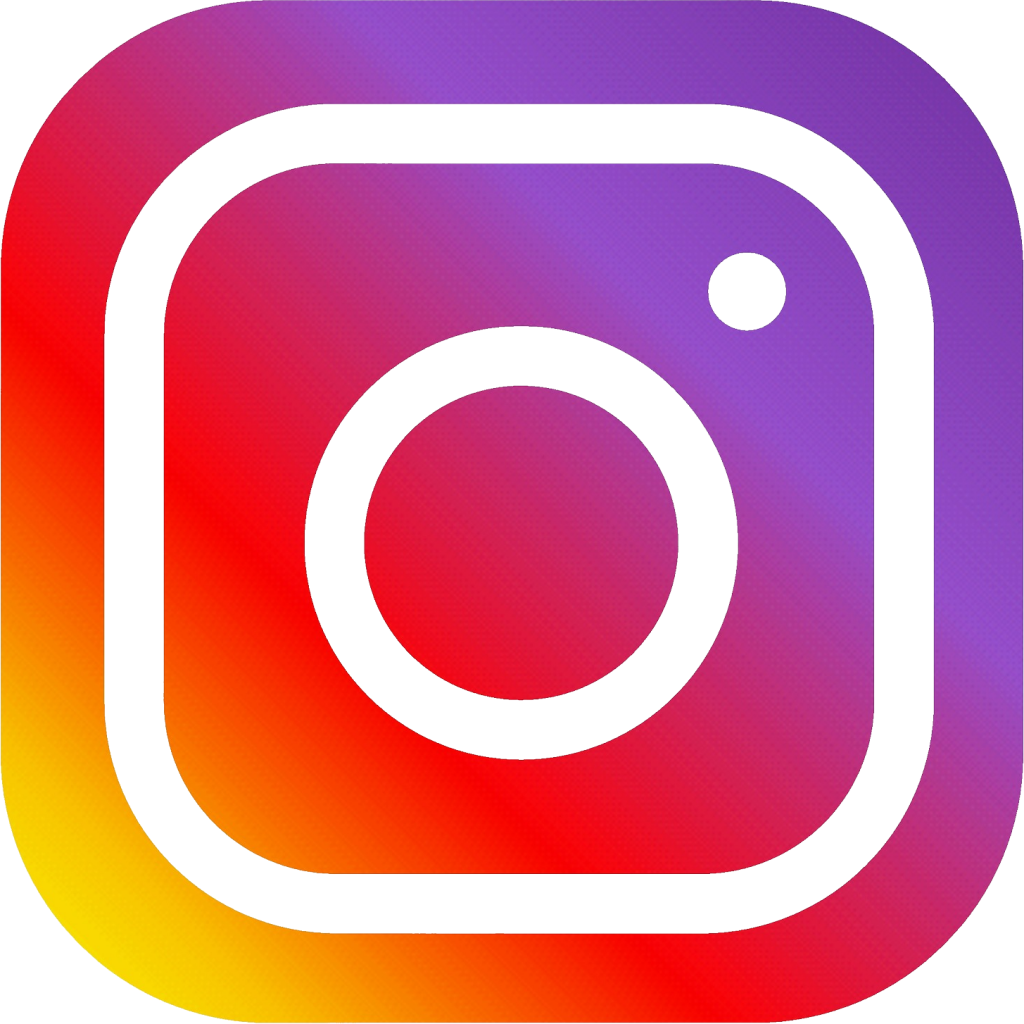 [https://www.instagram.com/fglongatt/](https://www.instagram.com/fglongatt/) 